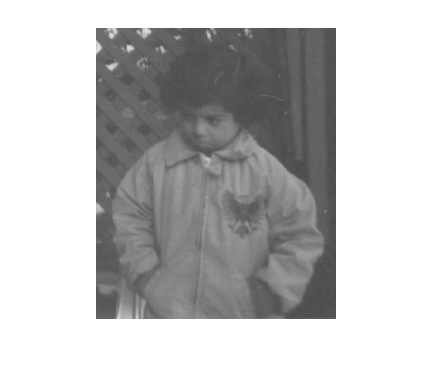

I = imread('pout.tif');
imshow(I)

whos

  Name        Size             Bytes  Class     Attributes

  I         291x240            69840  uint8               
  I2        291x240            69840  uint8               
  ans         1x1               4230  struct              



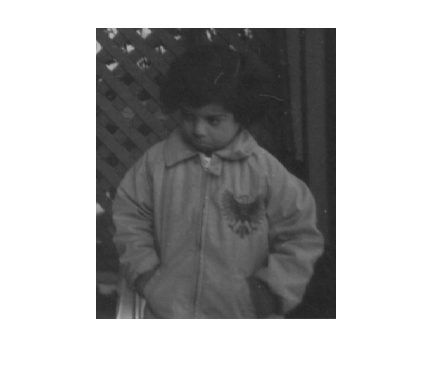

I2 = I - 40;
figure, imshow(I2)

imwrite(I2, 'pout2.png')
imformats

 
EXT       ISA     INFO        READ      WRITE     ALPHA  DESCRIPTION                     
-----------------------------------------------------------------------------------------
bmp       isbmp   imbmpinfo   readbmp   writebmp  0      Windows Bitmap
cur       iscur   imcurinfo   readcur             1      Windows Cursor resources
fts fits  isfits  imfitsinfo  readfits            0      Flexible Image Transport System
gif       isgif   imgifinfo   readgif   writegif  0      Graphics Interchange Format
hdf       ishdf   imhdfinfo   readhdf   writehdf  0      Hierarchical Data Format
ico       isico   imicoinfo   readico             1      Windows Icon resources
j2c j2k   isjp2   imjp2info   readjp2   writej2c  0      JPEG 2000 (raw codestream)
jp2       isjp2   imjp2info   readjp2   writejp2  0      JPEG 2000 (Part 1)
jpf jpx   isjp2   imjp2info   readjp2             0      JPEG 2000 (Part 2)
jpg jpeg  isjpg   imjpginfo   readjpg   writejpg  0      Joint Photographic Experts Group
pb

imfinfo('pout2.png')

ans = struct with fields:
                  Filename: '/home/sean/Desktop/CS697_DigitalImageProcessing/pout2.png'
               FileModDate: '12-Sep-2021 11:33:48'
                  FileSize: 31442
                    Format: 'png'
             FormatVersion: []
                     Width: 240
                    Height: 291
                  BitDepth: 8
                 ColorType: 'grayscale'
           FormatSignature: [137 80 78 71 13 10 26 10]
                  Colormap: []
                 Histogram: []
             InterlaceType: 'none'
              Transparency: 'none'
    SimpleTransparencyData: []
           BackgroundColor: []
           RenderingIntent: []
            Chromaticities: []
                     Gamma: []
               XResolution: []
               YResolution: []
            ResolutionUnit: []
                   XOffset: []
                   YOffset: []
                OffsetUnit: []
           SignificantBits: []
              ImageModTime: '12 Sep 2021 15

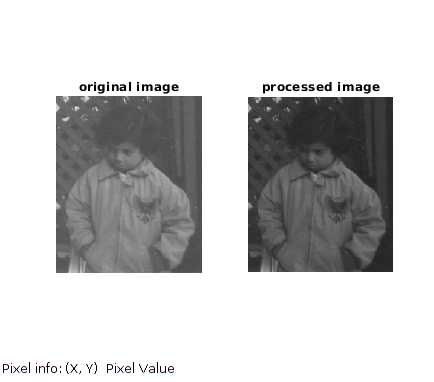

subplot(1,2,1),imshow(I),title('original image'),
subplot(1,2,2),imshow(I2),title('processed image');
impixelinfo;

[rows cols] = size(I);
girlImage = imread('pout.tif');
inverseGirlImage = 255 - girlImage;
